## HW2, Exercise 1b: Sketch the wavefunction 

### Set the constants

L = 1; % Assuming unit box length for simplicity
A = 1; % Assuming unit amplitude for simplicity
n_points = 1000; % Number of points for plotting
x = linspace(-L/2, L/2, n_points);

### Define the equations for the Wave functions

psi_0 = sqrt(2/L) * sin(pi*(x + L/2)/L);
psi_1 = sqrt(2/L) * sin(2*pi*(x + L/2)/L);
psi_2 = sqrt(2/L) * sin(3*pi*(x + L/2)/L);

### Transitions (i=>f)

% For i=0 -> f=1
product_0_1 = psi_0 .* x .* psi_1;

% For i=0 -> f=2
product_0_2 = psi_0 .* x .* psi_2;

### Sketch the functions

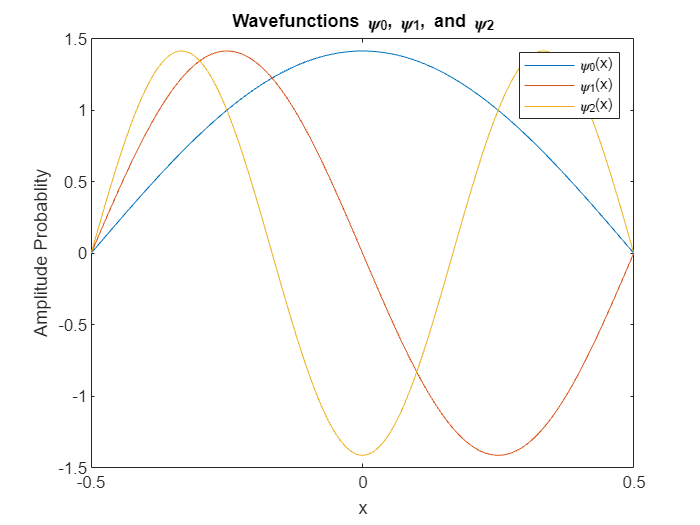

figure;

% Plotting phi_0, phi_1, and phi_2 on the same graph
figure;
plot(x, psi_0, 'DisplayName', '\psi_0(x)');
hold on;
plot(x, psi_1, 'DisplayName', '\psi_1(x)');
plot(x, psi_2, 'DisplayName', '\psi_2(x)');
hold off;
legend('show');
title('Wavefunctions \psi_0, \psi_1, and \psi_2');
xlabel('x');
ylabel('Amplitude Probablity');

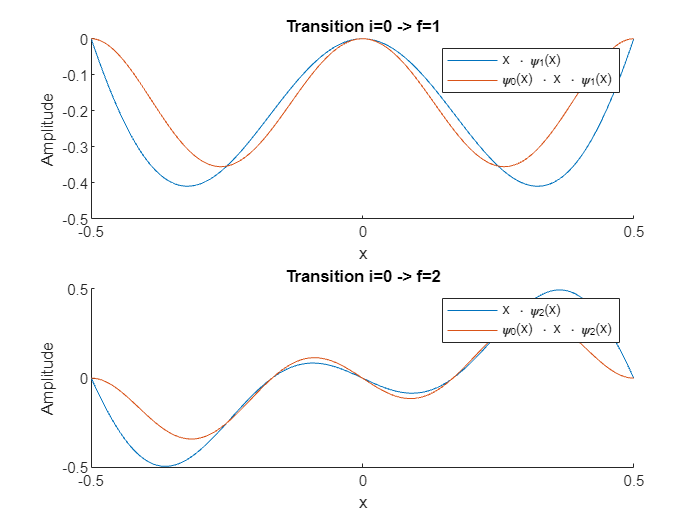


% i=0 -> f=1
subplot(2,1,1);
%plot(x, psi_0, 'DisplayName', '\psi_0(x)');
hold on;
plot(x, x .* psi_1, 'DisplayName', 'x \cdot \psi_1(x)');
plot(x, product_0_1, 'DisplayName', '\psi_0(x) \cdot x \cdot \psi_1(x)');
hold off;
legend('show');
title('Transition i=0 -> f=1');
xlabel('x');
ylabel('Amplitude');


% i=0 -> f=2
subplot(2,1,2);
%plot(x, psi_0, 'DisplayName', '\psi_0(x)');
hold on;
plot(x, x .* psi_2, 'DisplayName', 'x \cdot \psi_2(x)');
plot(x, product_0_2, 'DisplayName', '\psi_0(x) \cdot x \cdot \psi_2(x)');
hold off;
legend('show');
title('Transition i=0 -> f=2');
xlabel('x');
ylabel('Amplitude');